clc; clear;

img = imread('bby 1.png');
[rows, cols, layers] = size(img)

rows = 852

cols = 661

layers = 3


%% Original Image

disp('============== Original Image ================')

============== Original Image ================


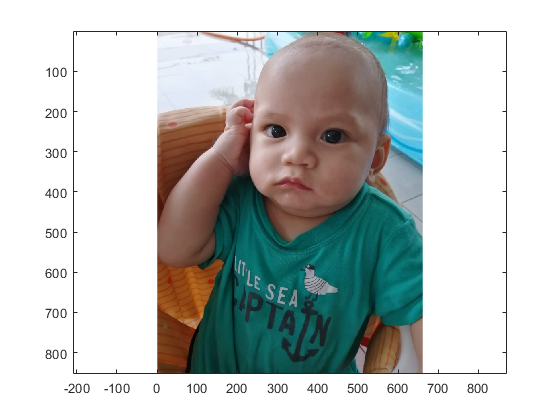

figure
image(img);
axis on; axis equal;


%% K1 - Sharpen

disp('================= Sharpen ===================')

================= Sharpen ===================


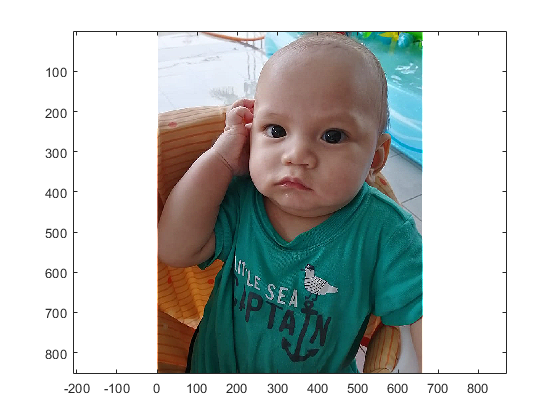

k1 = [0 -1 0; -1 5 -1; 0 -1 0];
S1 = uint8(convn(img,k1,'same'));
figure
image(S1)
axis on; axis equal;


%% K2 - Edge Detection

disp('============== Edge Detection ================')

============== Edge Detection ================


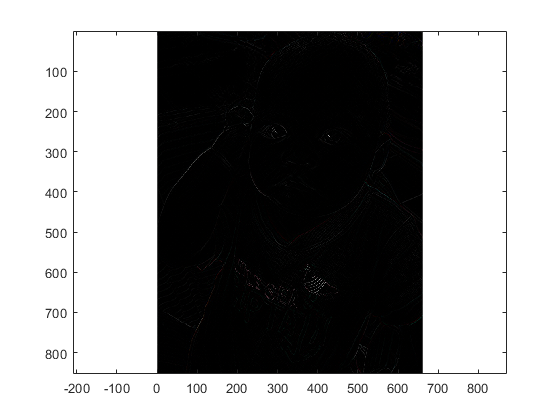

k2 = [1 0 -1; 0 0 0; -1 0 1];
S2 = uint8(convn(img,k2,'same'));
figure
image(S2)
axis on; axis equal;


%% K3 - Gaussion Blur

disp('============== Gaussion Blur ================')

============== Gaussion Blur ================


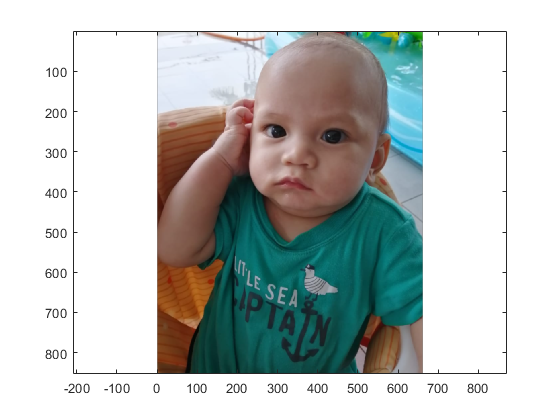

k3 = (1/16) * [1 2 1; 2 4 2; 1 2 1];
S3 = uint8(convn(img,k3,'same'));
figure
image(S3)
axis on; axis equal;

## Part 5 (ii)

%%Convolution

disp('============== Part 5 (ii) ================')

============== Part 5 (ii) ================


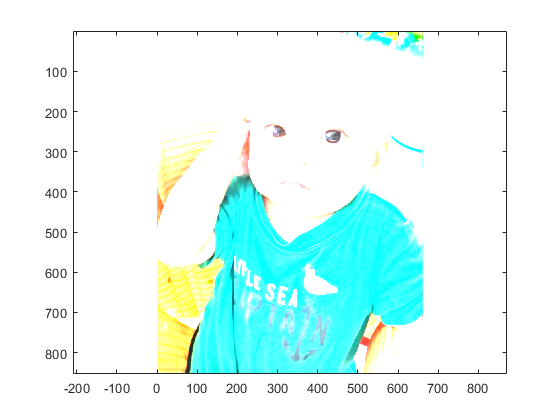

p5 = [1 1 1; 1 1 0; 1 0 0];
S4 = uint8(convn(img,p5,'same'));
figure
image(S4)
axis on; axis equal;

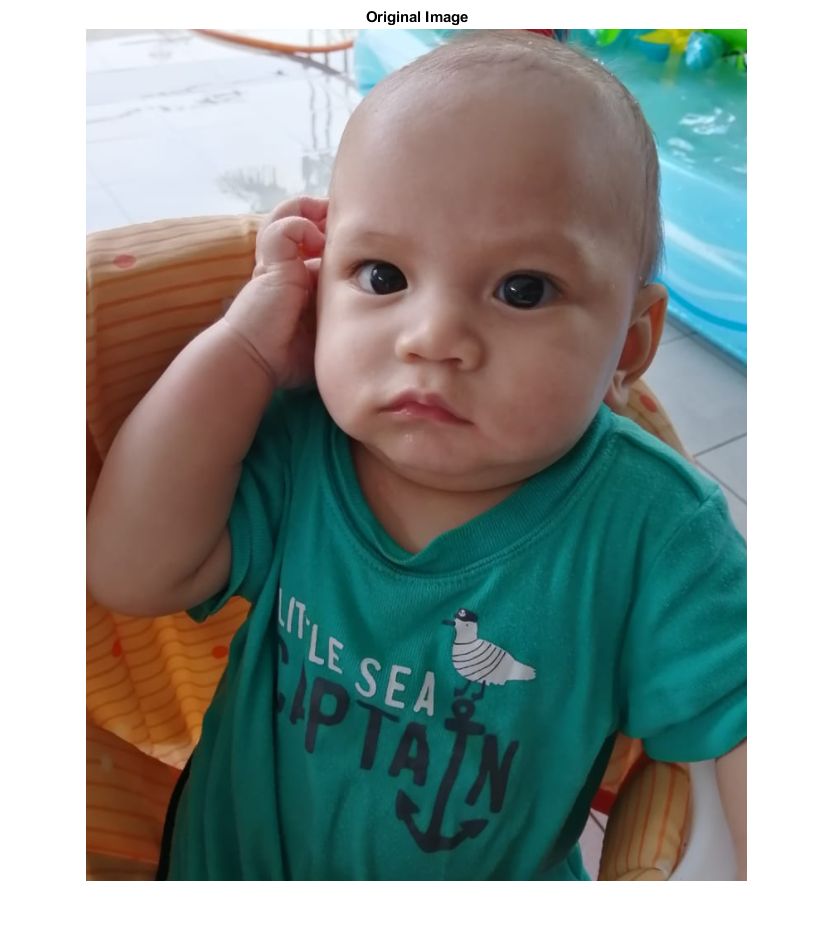


%%Correlation

at=rgb2gray(img);
figure;
imshow(img);
title('Original Image');

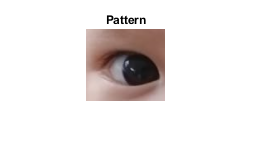

bt=imread('bby 1 eye.png'); %crop image from original
b=rgb2gray(bt);
figure;
imshow(bt);
title('Pattern');

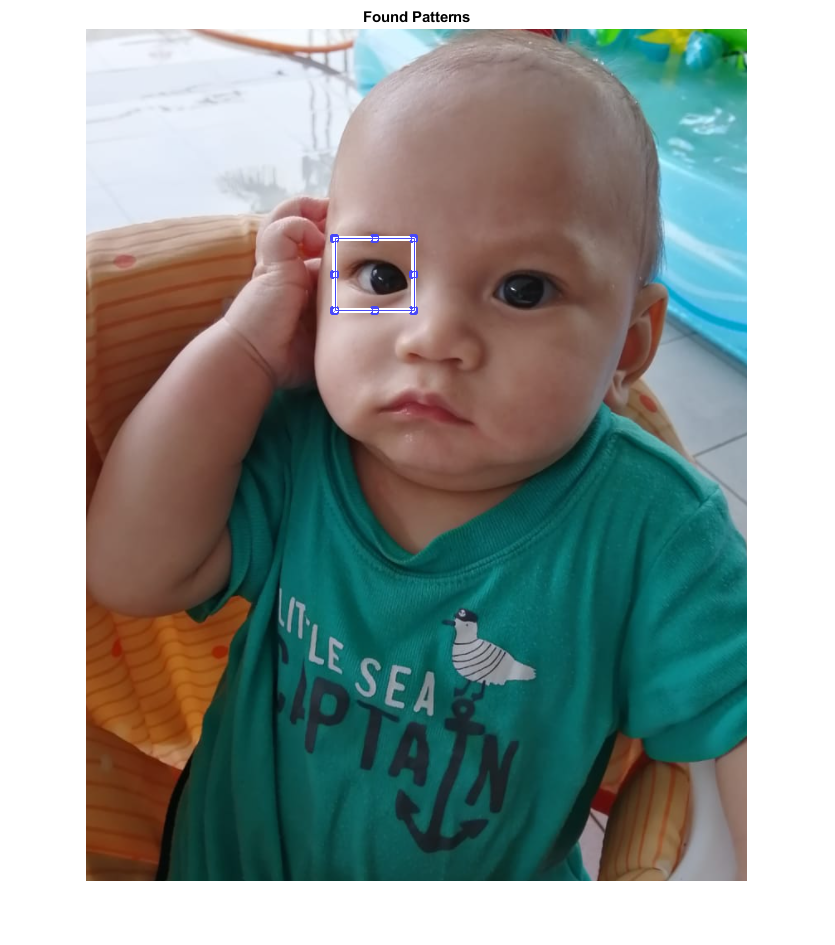

cross=normxcorr2(b,at); %cross correlation of the image

[y x]=find(cross>=0.98*max(cross(:)));
ynew=y-size(b,1);
xnew=x-size(b,2);

figure;
imshow(img);
    
    for i=1:length(xnew)
        %show rectangular shape around baby's eye
        imrect(gca,[xnew(i)+1,ynew(i)+1,size(b,2),size(b,1)]);
        hold on;
    end

title('Found Patterns');